tic
clc;clear;close all;
% time = minute; length = centimeter;
Ts=0.4713;Tr=0.1044;a=0.0005;g=atand(1/3);ks=1.29e-7*100*3600;q=2.85e-6*100*3600/ks;Fae=0;
% A=3.032e-8;B=-1.172e-4;C=0.3269;
A=0;B=0;C=0.34;
H=1*100*a*cosd(g);
bm=load('bm18.txt'); % import the positive roots of transcendental equation from current folder


ZT=24;ZJ=101; % total analysis time (hour) and number of vertical node 
k=zeros(ZT+1,ZJ);
f=zeros(ZT+1,ZJ);
p=zeros(ZT+1,ZJ);
T=zeros(ZT+1,ZJ);

for i=0:1:ZT
    t=ks*a*i*cosd(g)^2/(Ts-Tr);
for j=1:ZJ
    z=(j-1)/(ZJ-1)*H;
    W=0;
for m=1:1000    
    
    Dm=(4*bm(m)+(3-4*bm(m)^2)*exp(H/2)*sin(bm(m)*H))/(1+4*bm(m)^2);
    Em=(16*bm(m)*(2*cos(bm(m)*H)*exp(H/2)-1)/(1+4*bm(m)^2)+(3-4*bm(m)^2)*exp(H/2)*H*sin(bm(m)*H))/(1+4*bm(m)^2);
    Fm=(C-Tr)*sin(bm(m)*H)*exp(H/2)/(Ts-Tr)+B*(sin(bm(m)*H)*H*exp(H/2)-Dm)/(a*cosd(g)*(Ts-Tr))+A*(sin(bm(m)*H)*H^2*exp(H/2)-2*Em)/(a^2*cosd(g)^2*(Ts-Tr));
    W=W+2*(bm(m)*cos(bm(m)*z)+0.5*sin(bm(m)*z))*((0.25+bm(m)^2)*exp(-bm(m)^2*t)*Fm+q*exp(H/2)*(bm(m)*cos(bm(m)*H)+0.5*sin(bm(m)*H))*(exp(t/4)-exp(-bm(m)^2*t)))/((H*(bm(m)^2+0.25)+1)*(0.25+bm(m)^2));
end
    k(i+1,j)=W*exp(-0.5*z-0.25*t);
    p(i+1,j)=k(i+1,j)*ks/100/3600;
    
    if(log(k(i+1,j))/a-Fae*100)/100<0
        f(i+1,j)=(log(k(i+1,j))/a-Fae*100)/100;
    else
        f(i+1,j)=0;
    end
    
    if k(i+1,j)*(Ts-Tr)+Tr<Ts
        T(i+1,j)=k(i+1,j)*(Ts-Tr)+Tr;
    else
        T(i+1,j)=Ts;
    end      
end
end

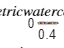

for j=1:ZJ
z(j)=(j-1)/ZJ*H/a/100/cosd(g);
end

for i=0:1:ZT
x(i+1,:)=T(i+1,:);
y=z(1,:)/100/a/cosd(g);
plot(x(i+1,:),y)
hold on;
end
hold off;
% legend('0h','4h','8h','12h','16h','20h','24h');
ylabel('$z/m$','Interpreter','latex'); 
xlabel('$Volumetric \ water \ cotent \ \theta$','Interpreter','latex'); 
title('$Volumetric water content profile$','Interpreter','latex')

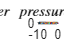


for i=0:1:ZT
x2(i+1,:)=f(i+1,:);
y=z(1,:)/100/a/cosd(g);
plot(x2(i+1,:),y)
hold on;
end
ylabel('$z/m$','Interpreter','latex'); 
xlabel('$Pore \ water \ pressure \ head \ h_{p}/m$','Interpreter','latex'); 
title('$Pore \ water \ pressure \ head \ profile$','Interpreter','latex');
hold off;

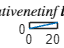


for i=0:24
    t1(i+1)=i;
    Q1(i+1)=q*ks*t1(i+1)*cosd(g)/1000;
    plot(t1,Q1)
end
title('$cumulative net infiltration/mm$','Interpreter','latex')

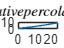


for i=0:24
p1(i+1,1)=p(i+1,1);
x3(i+1,1)=sum(p1(1:i+1,1))*1000*3600;
end
plot(t1,x3)
hold on;
title('$cumulative percolation/mm$','Interpreter','latex')
hold off;

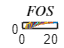

% To calculate FOS, the grid distance of cover should be 0.01 meter
% Please adjust the value of ZJ(line 10) or the code below
c=5.74;f1=26.6;fb=14.1;rd=14.2;rw=9.81;H1=1.0;
uw=f*9.81;
g1=T*0.01*rw;
for i=1:ZT+1
    for j=1:101
        z(j)=(j-1)/100*H1;
        g2=g1(i,:);        
        FOS(i,j)=(c-uw(i,j)*tand(fb))/((rd*(H1-z(j))+sum(g2(j:101)))*tand(g))+tand(f1)/tand(g);        
    end
end
for i=1:ZT
x4(i,:)=FOS(i,:);
y=z(1,:);
plot(x4(i,:),y)
ylim([0 0.8])

hold on;
end
title('$FOS$','Interpreter','latex')
hold off;